clear;

load("RMSE_int_Guss.mat")
RMSE_int_guss = RMSE;
load("RMSE_DoS_Guss.mat")
RMSE_DoS_guss = RMSE;
RMSEE = load("RMSE_int_imp.mat")

RMSEE = 包含以下字段的 struct :
    RMSE: [1×9 struct]


RMSE_int_imp = RMSEE.RMSE;
load("RMSE_DoS_imp.mat")
RMSE_DoS_imp = RMSE;
load("RMSE_int_levy12.mat")
RMSE_int_levy = RMSE;
load("RMSE_DoS_levy12.mat")
RMSE_DoS_levy = RMSE;
clear("RMSE")

num = 1;
DKF_i = 0;
DKF_d = 0;
DKMCF_i = 0;
DKMCF_d = 0;
TAKF_i = 0;
TAKF_d = 0;
TKF_i = 0;TKF_d = 0;
TKFs_i = 0;TKFs_d = 0;
for i = 6
DKF_i = DKF_i + RMSE_int_guss(i).DKF/num;
DKF_d = DKF_d + RMSE_DoS_guss(i).DKF/num;
DMCKF_i = DKF_i + RMSE_int_guss(i).DMCKF/num;
DMCKF_d = DKF_d + RMSE_DoS_guss(i).DMCKF/num;
TAKF_i = TAKF_i + RMSE_int_guss(i).TAKF/num;
TAKF_d = TAKF_d + RMSE_DoS_guss(i).TAKF/num; 
TKF_i = TKF_i + RMSE_int_guss(i).TKF/num;
TKF_d = TKF_d + RMSE_DoS_guss(i).TKF/num;
TKFs_i = TKFs_i + RMSE_int_guss(i).TKF_s/num;
TKFs_d = TKFs_d + RMSE_DoS_guss(i).TKF_s/num;

% DKF_i = DKF_i + RMSE_int_imp(i).DKF/num;
% DKF_d = DKF_d + RMSE_DoS_imp(i).DKF/num;
% DMCKF_i = DKF_i + RMSE_int_imp(i).DMCKF/num;
% DMCKF_d = DKF_d + RMSE_DoS_imp(i).DMCKF/num;
% TAKF_i = TAKF_i + RMSE_int_imp(i).TAKF/num;
% TAKF_d = TAKF_d + RMSE_DoS_imp(i).TAKF/num;
% TKF_i = TKF_i + RMSE_int_imp(i).TKF/num;
% TKF_d = TKF_d + RMSE_DoS_imp(i).TKF/num;
% TKFs_i = TKFs_i + RMSE_int_imp(i).TKF_s/num;
% TKFs_d = TKFs_d + RMSE_DoS_imp(i).TKF_s/num;

% DKF_i = DKF_i + RMSE_int_levy(i).DKF/num;
% DKF_d = DKF_d + RMSE_DoS_levy(i).DKF/num;
% DMCKF_i = DKF_i + RMSE_int_levy(i).DMCKF/num;
% DMCKF_d = DKF_d + RMSE_DoS_levy(i).DMCKF/num;
% 
% TAKF_i = TAKF_i + RMSE_int_levy(i).TAKF/num;
% TAKF_d = TAKF_d + RMSE_DoS_levy(i).TAKF/num;
% 
% TKF_i = TKF_i + RMSE_int_levy(i).TKF/num;
% TKF_d = TKF_d + RMSE_DoS_levy(i).TKF/num;
% TKFs_i = TKFs_i + RMSE_int_levy(i).TKF_s/num;
% TKFs_d = TKFs_d + RMSE_DoS_levy(i).TKF_s/num;

end


for i =1:5
   Rmean(i)= struct('G_i',0,'G_d',0, ...
       'imp_i',0,'imp_d',0,'levy_i',0,'levy_d',0);
end

   Rmean(1).G_i = mean([RMSE_int_guss.meanDKF]);
   Rmean(2).G_i = mean([RMSE_int_guss.meanDMCKF]);
   Rmean(3).G_i = mean([RMSE_int_guss.meanTAKF]);
   Rmean(4).G_i = mean([RMSE_int_guss.meanTKF]);
   Rmean(5).G_i = mean([RMSE_int_guss.meanTKF_s]);

Rmean(1).G_d = mean([RMSE_DoS_guss.meanDKF]);
Rmean(2).G_d = mean([RMSE_DoS_guss.meanDMCKF]);
Rmean(3).G_d = mean([RMSE_DoS_guss.meanTAKF]);
Rmean(4).G_d= mean([RMSE_DoS_guss.meanTKF]);
Rmean(5).G_d = mean([RMSE_DoS_guss.meanTKF_s]);


Rmean(1).imp_i = mean([RMSE_int_imp.meanDKF]);
Rmean(2).imp_i = mean([RMSE_int_imp.meanDMCKF]);
Rmean(3).imp_i = mean([RMSE_int_imp.meanTAKF]);
Rmean(4).imp_i = mean([RMSE_int_imp.meanTKF]);
Rmean(5).imp_i = mean([RMSE_int_imp.meanTKF_s]);

Rmean(1).imp_d = mean([RMSE_DoS_imp.meanDKF]);
Rmean(2).imp_d = mean([RMSE_DoS_imp.meanDMCKF]);
Rmean(3).imp_d = mean([RMSE_DoS_imp.meanTAKF]);
Rmean(4).imp_d = mean([RMSE_DoS_imp.meanTKF]);
Rmean(5).imp_d = mean([RMSE_DoS_imp.meanTKF_s]);

Rmean(1).levy_i = mean([RMSE_int_levy.meanDKF]);
Rmean(2).levy_i = mean([RMSE_int_levy.meanDMCKF]);
Rmean(3).levy_i = mean([RMSE_int_levy.meanTAKF]);
Rmean(4).levy_i = mean([RMSE_int_levy.meanTKF]);
Rmean(5).levy_i = mean([RMSE_int_levy.meanTKF_s]);

Rmean(1).levy_d = mean([RMSE_DoS_levy.meanDKF]);
Rmean(2).levy_d = mean([RMSE_DoS_levy.meanDMCKF]);
Rmean(3).levy_d = mean([RMSE_DoS_levy.meanTAKF]);
Rmean(4).levy_d = mean([RMSE_DoS_levy.meanTKF]);
Rmean(5).levy_d = mean([RMSE_DoS_levy.meanTKF_s]);



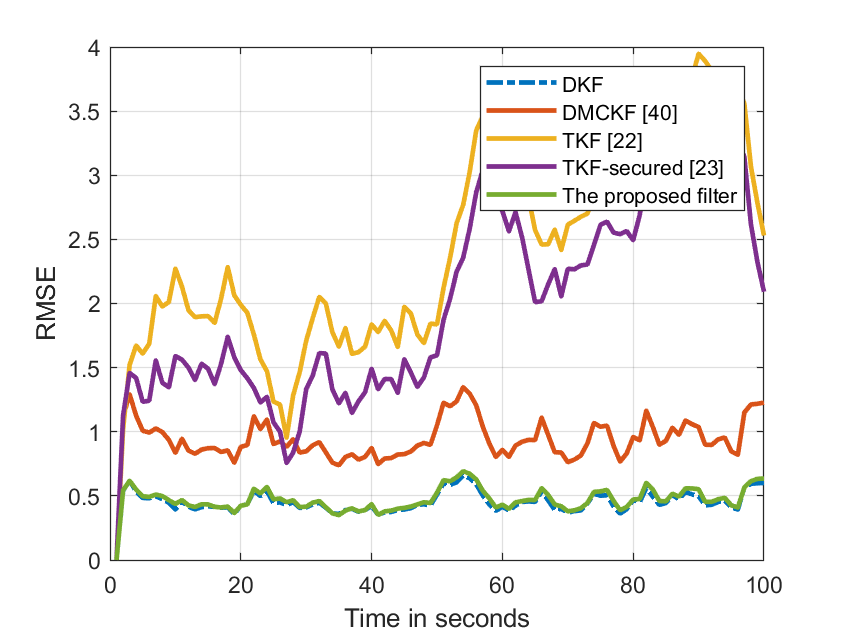

txt1 = {'DKF','DMCKF [40]','TKF [22]','TKF-secured [23]','The proposed filter'};

figure()
hold on
grid on
box on
plot(DKF_i,'-.',LineWidth=2)
plot(DMCKF_i,'-',LineWidth=2)
plot(TKF_i,'-',LineWidth=2)
plot(TKFs_i,'-',LineWidth=2)
plot(TAKF_i,'-',LineWidth=2)
legend(txt1)
xlabel('Time in seconds');ylabel('RMSE');
hold off
print(gcf,'-depsc2','DOS-g-a.eps');

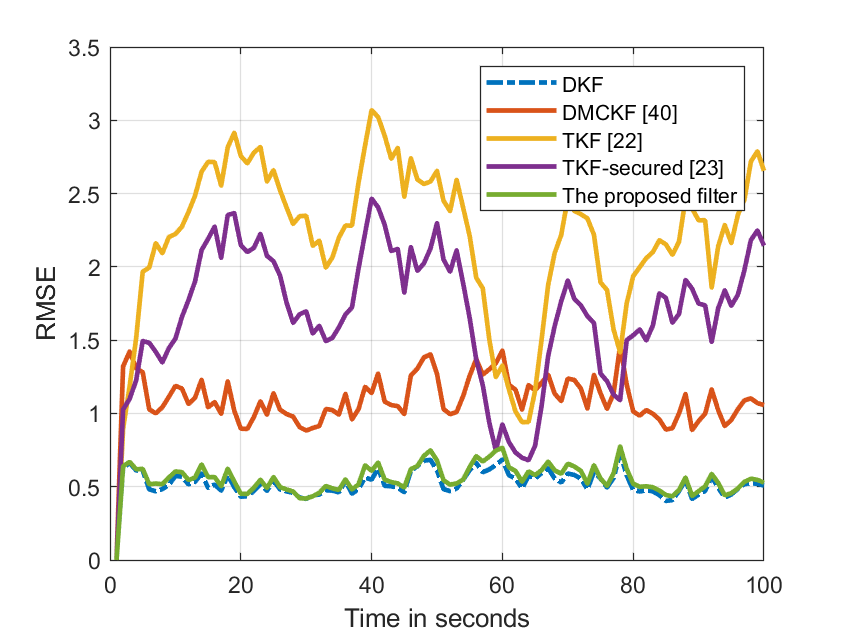


figure()
hold on
grid on
box on
plot(DKF_d,'-.',LineWidth=2)
plot(DMCKF_d,'-',LineWidth=2)
plot(TKF_d,'-',LineWidth=2)
plot(TKFs_d,'-',LineWidth=2)
plot(TAKF_d,'-',LineWidth=2)
legend(txt1)
xlabel('Time in seconds');ylabel('RMSE');
hold off
print(gcf,'-depsc2','DOS-g-b.eps');